We have to execute a specific task with a redundant robot.

We want to do it finding the minimum norm $\mathbf{\dot{q}}$, so we have to use the pseudoinverse of the Jacobian.

In particular using the **pseudo Inverse      **$\dot{q}=J^\#(q))\dot{r_{des}}$      that can be computed in two ways:     

Note that if $\dot{r}\in Range(J(q))$ we do not have task error and we have the minimum norm of the joint velocities so the quantity $||\dot{q}||^2=\dot{q}^T\dot{q}$ is the minimum among the many.

else if this is not the case this solution minimize the quantity $||\dot{q}||^2=\dot{q}^T\dot{q}$ but **we have a task error** $||\dot{r}-J(q)\dot{q}||^2$ **that is the minimum possible**

- If the jacobian J is full raw rank we have:  (se dim(J)=2x3 e il rango è 2)

                            
$$J^\#=J^T(JJ^T)^{-1}$$


- If this is not the case we have to use the Singular Value Decomposition SVD:

                            $J=U_{MxM}\Sigma_{MxN} V_{NxN}^T$   where   $\Sigma=[\sigma_{MxM} \ 0_{Mx(N-M)}]$   where $\sigma $ is a diagonal matrix composed

                            by elemets $\sigma_1\geq\sigma_2\geq ...\geq \sigma_\rho>0$ and >$\sigma_{\rho+1}=...=\sigma_M=0$ where $rank(J)=\rho$ .

          and we have that:

         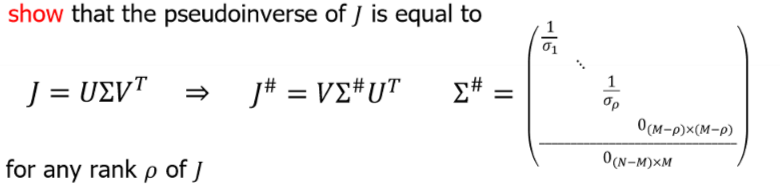

In both cases we can use a **Weighted     **$\dot{q}=J_W^\#(q))\dot{r_{des}}$        version of this relationsghip given by th consideration of **W>0** weight matrix SYMMETRIC or **DIAGONAL**, and rememebre that if we have a big weight this implies a small velocity. Nel particolare sono importanti le dimensioni reciproche fra le dimensioni di W.

And in this case we have: 

- If the jacobian J is full raw rank we have:  (se dim(J)=2x3 e il rango è 2)

                            $J_W^\#=W^{-1}J^T(JW^{-1}J^T)^{-1}$           or       $J_W^\#=W^{-\ \frac{1}{2}} pinv(J_{aux}) $     where $J_{aux}=JW^{-\ \frac{1}{2}}$

- If this is not the case we have to use the Singular Value Decomposition SVD:

                            $J_W^\#$ is obtained considering $J_W^\#=W^{-\ \frac{1}{2}}pinv(J_{aux})$        where   $J_{aux}=JW^{-\ \frac{1}{2}}$

Moreover we have another kind of solution provided by the Damped Least Square method (**DLS**) very usefull when we obtain a very high joint velocity, and we make a compromise between the large joint velocity and the task accuracy using a coefficient $\mu$.

We make an unconstrained minimization of this objective function:

$min_\dot{q} \ \{H(q)\}= min_\dot{q} \{ \frac{\mu^2}{2} ||\dot{q}|| + \frac{1}{2}||\dot{r}-J\dot{q}||^2 \}$    and the solution is given by:     $\dot{q}_{DLS}=J_{DLS}(q)\dot{r}=J^T(JJ^T+\mu^2I_M)^{-1}\dot{r}$

We can use also singular values on $J_{DLS}$.

Let's stat to considering an exercise:

%dimension of the tasks
m=2;
n=3;

%Define The Direct Kinematics or provide a Jacobian
syms q1 q2 q3 q4;
q=[q1;q2;q3;q4];

%Px=cos(q1)+cos(q1+q2)+cos(q1+q2+q3)+cos(q1+q2+q3+q4);
%Py=sin(q1)+sin(q1+q2)+sin(q1+q2+q3)+sin(q1+q2+q3+q4);
%P=[Px;Py]
%J_sym=jacobian(P,q);


**Note now that all these exercises requires to find a desider joint velocity given a initial configuration and a desider cartesian velocity**

%q_initial=[0;pi/6;-pi/3;-pi/3]
V_des=[2;1]

V_des =      2
     1


Now let's evaluate the Jacobian in the initial configuration

%J=round(double(subs(J_sym,q,q_initial)),4)
J=[3 1 2; 1.5 0.5 1]

J =     3.0000    1.0000    2.0000
    1.5000    0.5000    1.0000


parametro da sceliere per eseguire diverse porzioni di codice

x=1 psueudoInverse Solution (Minimum nomr of qdot and task error if it exists)

x=2 WEIGHTED pseudoInverse Solution

x=3 Damped LeastSquare solution

x=1; 

**Pseudo inverse solution   **$\dot{q}=J^\#(q))\dot{r_{des}}$   ---------------------------------------------------------------------------------

First of all let's see if the jacobian is full raw rank

if(x==1)
dimJ=size(J);
if(rank(J)<dimJ(1,1))
    isJFullRawRank=false
else
    isJFullRawRank=true;
end
isJFullRawRank

Now let's check if we'll have a task error:

if (rank(J)==rank([J,V_des]))
    task_error=false;
    disp('NO, DO NOT HAVE TASK ERROR so v_des \in Range(J) ')
else
    task_error=true;
    disp('YES,We HAVE TASK ERROR so v_des NOT \in Range(J)')
end


$$||\dot{r}-J(q)\dot{q}||^2$$


if(isJFullRawRank)

            $J|_{q_0}$ is full rank so we can apply the psedoinverse formula: $J^\#=J^T(JJ^T)^{-1}$

    qdot=round(double((pinv(J)*V_des)),4)
    %qdot=round(double(simplify(pinv(J)*Ve_des)),4)
end
if(~isJFullRawRank)

            We need to compute $J^\#$ using the SVD

    [U,S,V]=svd(J);
    S_cancelletto=zeros(n,m);
    for i=1:rank(J)
        for j=1:rank(J)
            if(i==j)
                S_cancelletto(i,i)=1/S(i,j);
            end
        end
    end
    S_cancelletto % deve avere n righe e m colonne
    pseudoInv_J=round(double(V*S_cancelletto*transpose(U)),4)
    qdot=round(double((pseudoInv_J*V_des)),4)
end
end

isJFullRawRank = logical
   0


isJFullRawRank = logical
   0


NO, DO NOT HAVE TASK ERROR so v_des \in Range(J) 


S_cancelletto =     0.2390         0
         0         0
         0         0


pseudoInv_J =     0.1714    0.0857
    0.0571    0.0286
    0.1143    0.0571


qdot =     0.4285
    0.1428
    0.2857


**WEIGHTED Pseudo inverse solution     **$\dot{q}=J_W^\#(q))\dot{r_{des}}$ -------------------------------------------------------------------------------

if(x==2)

%define the Weight matrix
W=eye(n,n)  % DEVE ESSERE UNA nxn

dimJW=size(J);
if(rank(J)<dimJ(1,1))
    isJFullRawRank=false
else
    isJFullRawRank=true;
end
isJFullRawRank

if(isJFullRawRank)

            $J|_{q_0}$ is full rank so we can apply the psedoinverse formula: $J_W^\#=W^{-1}J^T(JW^{-1}J^T)^{-1}$

    %pinv_Jw=simplify(inv(W)*transpose(J)*inv( J*inv(W)*transpose(J) ) )
    pinv_Jw=inv(W)*transpose(J)*inv( J*inv(W)*transpose(J) ) 
    qdot=round(double(pinv_Jw*V_des ),4)
    
end
if(~isJFullRawRank) % can use the general formula

            We need to compute $J_W^\#$ using the SVD $J_W^\#=W^{-\ \frac{1}{2}}pinv(J_{aux})$        where   $J_{aux}=JW^{-\ \frac{1}{2}}$

    %pinv_Jw=simplify(inv(W)^1/2*pinv(J*inv(W)^1/2))
    pinv_Jw=inv(W)^1/2*pinv(J*inv(W)^1/2)
    qdot=round(double(pinv_Jw*V_des ),4)
end
end

**Dampd Least square  **-----------------------------------------------------------------------------------------------------------------------------

We make and unconstrained minimization of this objective function:

$min_\dot{q} \ \{H(q)\}= min_\dot{q} \{ \frac{\mu^2}{2} ||\dot{q}|| + \frac{1}{2}||\dot{r}-J\dot{q}||^2 \}$    and the solution is given by:     $\dot{q}_{DLS}=J_{DLS}(q)\dot{r}=J^T(JJ^T+\mu^2I_M)^{-1}\dot{r}$

if(x==3)
    mu=0.5 %occhio che di solito ti forniscono mu^2
    q_DLS_dot=round(transpose(J)*round(inv(J*transpose(J)+(eye(m)*mu^2)),4)*V_des,4)
end %end dello switch

if(x~=1 && x~=2 && x~=3)
    error('Hai sbagliato a scegliere il parametro x')
end